# Implementacja algorytmu radix-2

Generowanie losowych danych

N = 1024;
xCpp = randn(N,2); 
xMat = xCpp(:,1) + xCpp(:,2).*1i;
save('x.mat','xMat');
% save('xcpp.dat','xCpp','-ascii');

fid=fopen('xcpp.dat','w');
fprintf(fid,'%.17f %.17f\n',xCpp);
fclose(fid);


Data test:

xCppTest = load('xcpp.dat');
%xMatTest = load('x.mat').xMat;
xMatTest = xMat;

XCppTest = fft(xCppTest(:,1)+xCppTest(:,2).*1i);
XMatTest = fft(xMatTest);



diffrece = sum(XMatTest-XCppTest)

diffrece =       1.534772309241816e-12 + 1.082508164873032e+02i


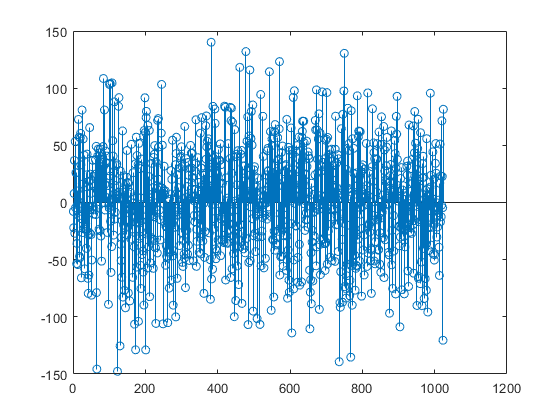


clf
figure
stem(real(XCppTest) - real(XMatTest))

Wczytywanie wynikow:

XCppDoubleFile = load('XcppDouble.txt');
XCppFloatfile = load('XcppFloat.txt');

XCppDouble = XCppDoubleFile(:,1)+XCppDoubleFile(:,2).*1i;
XCppFloat = XCppFloatfile(:,1)+XCppFloatfile(:,2).*1i;

diffrece2 = sum(XMatTest-XCppDouble)

diffrece2 = 0.0010 + 0.0014i

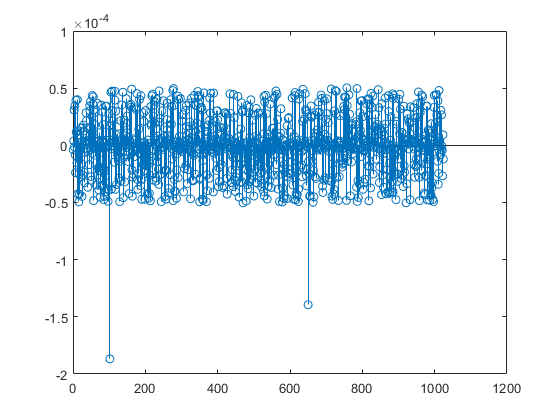


clf
figure
stem(real(XCppDouble) - real(XMatTest));


diffrece3 = sum(XMatTest-XCppFloat)

diffrece3 = 0.0004 + 0.0018i

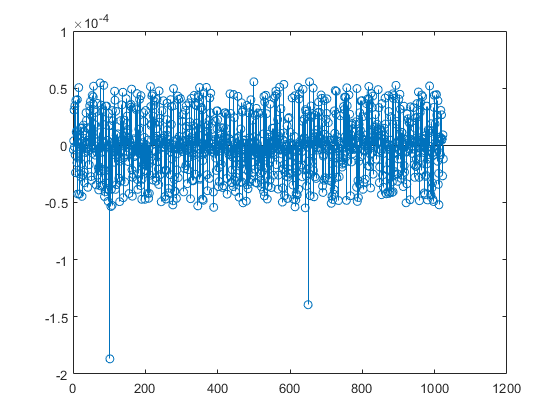


clf
figure
stem(real(XCppFloat) - real(XMatTest));